  close all; clc;

    %% (1) TIMING
    rng(42);                    
    ns   = 1:10;
    tRec = nan(size(ns));
    tGE  = nan(size(ns));
    dRec = nan(size(ns));
    dGE  = nan(size(ns));

    fprintf('--- Timing experiment (randn matrices) ---\n');

--- Timing experiment (randn matrices) ---


    for idx = 1:numel(ns)
        n = ns(idx);
        A = randn(n,n);

        % recursive timing
        tic;
        dRec(idx) = detA_recursive(A);
        tRec(idx) = toc;

        % GE timing
        tic;
        dGE(idx)  = detA_GE(A);
        tGE(idx)  = toc;

        fprintf('n=%2d | time(rec)=%.4fs  time(GE)=%.4fs  | det diff=%.3e\n', ...
            n, tRec(idx), tGE(idx), abs(dRec(idx)-dGE(idx)));
    end

n= 1 | time(rec)=0.0004s  time(GE)=0.0001s  | det diff=0.000e+00
n= 2 | time(rec)=0.0000s  time(GE)=0.0000s  | det diff=0.000e+00
n= 3 | time(rec)=0.0000s  time(GE)=0.0000s  | det diff=9.714e-17
n= 4 | time(rec)=0.0001s  time(GE)=0.0000s  | det diff=3.886e-16
n= 5 | time(rec)=0.0002s  time(GE)=0.0001s  | det diff=0.000e+00
n= 6 | time(rec)=0.0013s  time(GE)=0.0000s  | det diff=7.105e-15
n= 7 | time(rec)=0.0092s  time(GE)=0.0001s  | det diff=1.776e-15
n= 8 | time(rec)=0.0730s  time(GE)=0.0001s  | det diff=6.821e-13
n= 9 | time(rec)=0.6349s  time(GE)=0.0002s  | det diff=1.377e-13
n=10 | time(rec)=6.4769s  time(GE)=0.0002s  | det diff=1.847e-13


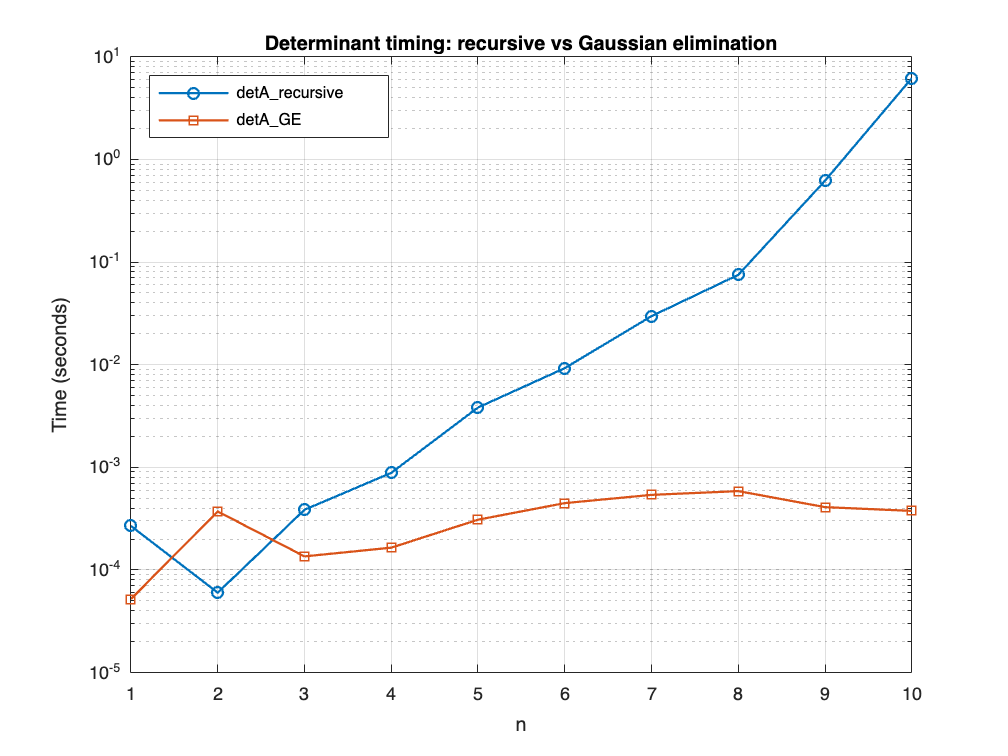


    % plot: time vs n
    figure('Color','w');
    plot(ns, tRec, '-o', 'LineWidth',1.25, 'MarkerSize',6); hold on;
    plot(ns, tGE , '-s', 'LineWidth',1.25, 'MarkerSize',6);
    ylabel('Time (seconds)'); xlabel('n');
    title('Determinant timing: recursive vs Gaussian elimination');
    legend({'detA\_recursive','detA\_GE'}, 'Location','northwest');
    grid on;
    set(gca,'YScale','log'); %(makes growth difference obvious)
    saveas(gcf, 'timing_recursive_vs_GE.png');



   fprintf('\n--- Round-off sensitivity (diagonal D) ---\n');


--- Round-off sensitivity (diagonal D) ---


    n = 1000;
    lambda = 1/100;                 
    D = diag(lambda*ones(n,1));

    % GE-based determinant (will underflow in double precision)
    dD_GE = detA_GE(D);

    % True value in exact arithmetic: lambda^n
    true_det = lambda^n;              

    % det(D) = prod(diag) = lambda^n, so log|det(D)| = n*log(lambda), sign = +1
    logAbsDet = n*log(lambda);
    signDet   = 1;

    fprintf('n = %d, lambda = %.2g\n', n, lambda);

n = 1000, lambda = 0.01


    fprintf('detA_GE(D)        = %.5g   (double precision; underflow expected)\n', dD_GE);

detA_GE(D)        = 0   (double precision; underflow expected)


    fprintf('sign(det(D))      = %d\n', signDet);

sign(det(D))      = 1


    fprintf('log(|det(D)|)     = %.5f  ->  |det(D)| = exp(logAbsDet) ~ 10^{%.1f}\n', ...
            logAbsDet, logAbsDet/log(10));

log(|det(D)|)     = -4605.17019  ->  |det(D)| = exp(logAbsDet) ~ 10^{-2000.0}



    % D is diagonal with nonzero diagonal entries => mathematically invertible.
    if lambda ~= 0
    hasInverse = true;
    else
    hasInverse = false;
    end

    if hasInverse
    invertibility = 'YES';
    else
    invertibility = 'NO';
    end
    fprintf('Is D invertible?  %s (all diagonal entries nonzero)\n', invertibility);

Is D invertible?  YES (all diagonal entries nonzero)



    fprintf('Note: The exact determinant is lambda^n = (1/100)^{1000} = 10^{-2000},\n');

Note: The exact determinant is lambda^n = (1/100)^{1000} = 10^{-2000},


    fprintf('      which is far below double-precision min (~5e-324), so it underflows to 0.\n');

      which is far below double-precision min (~5e-324), so it underflows to 0.
